# Week 10 Crane Lab (3D Acceleration Kinematics)

**Written by:        **Caiden Bonney

**Created:            **3/18/25

**Modified:          ** 3/19/25

**Background:     **

This lab builds on last week’s velocity analysis by focusing on acceleration kinematics of 3D rigid bodies. The crane undergoes three motions: turning, lifting, and extending. Due to changing angular velocities, a rotating frame of reference simplifies calculations. Using the 5-term acceleration equation and MATLAB for numerical integration, the position, velocity, and acceleration of the crane’s end are determined in a fixed frame.

**Required Files:**

- ME326_05_Activity7_BonneyCaiden_MatLabFile

- Bar.stl

## Task 1: 

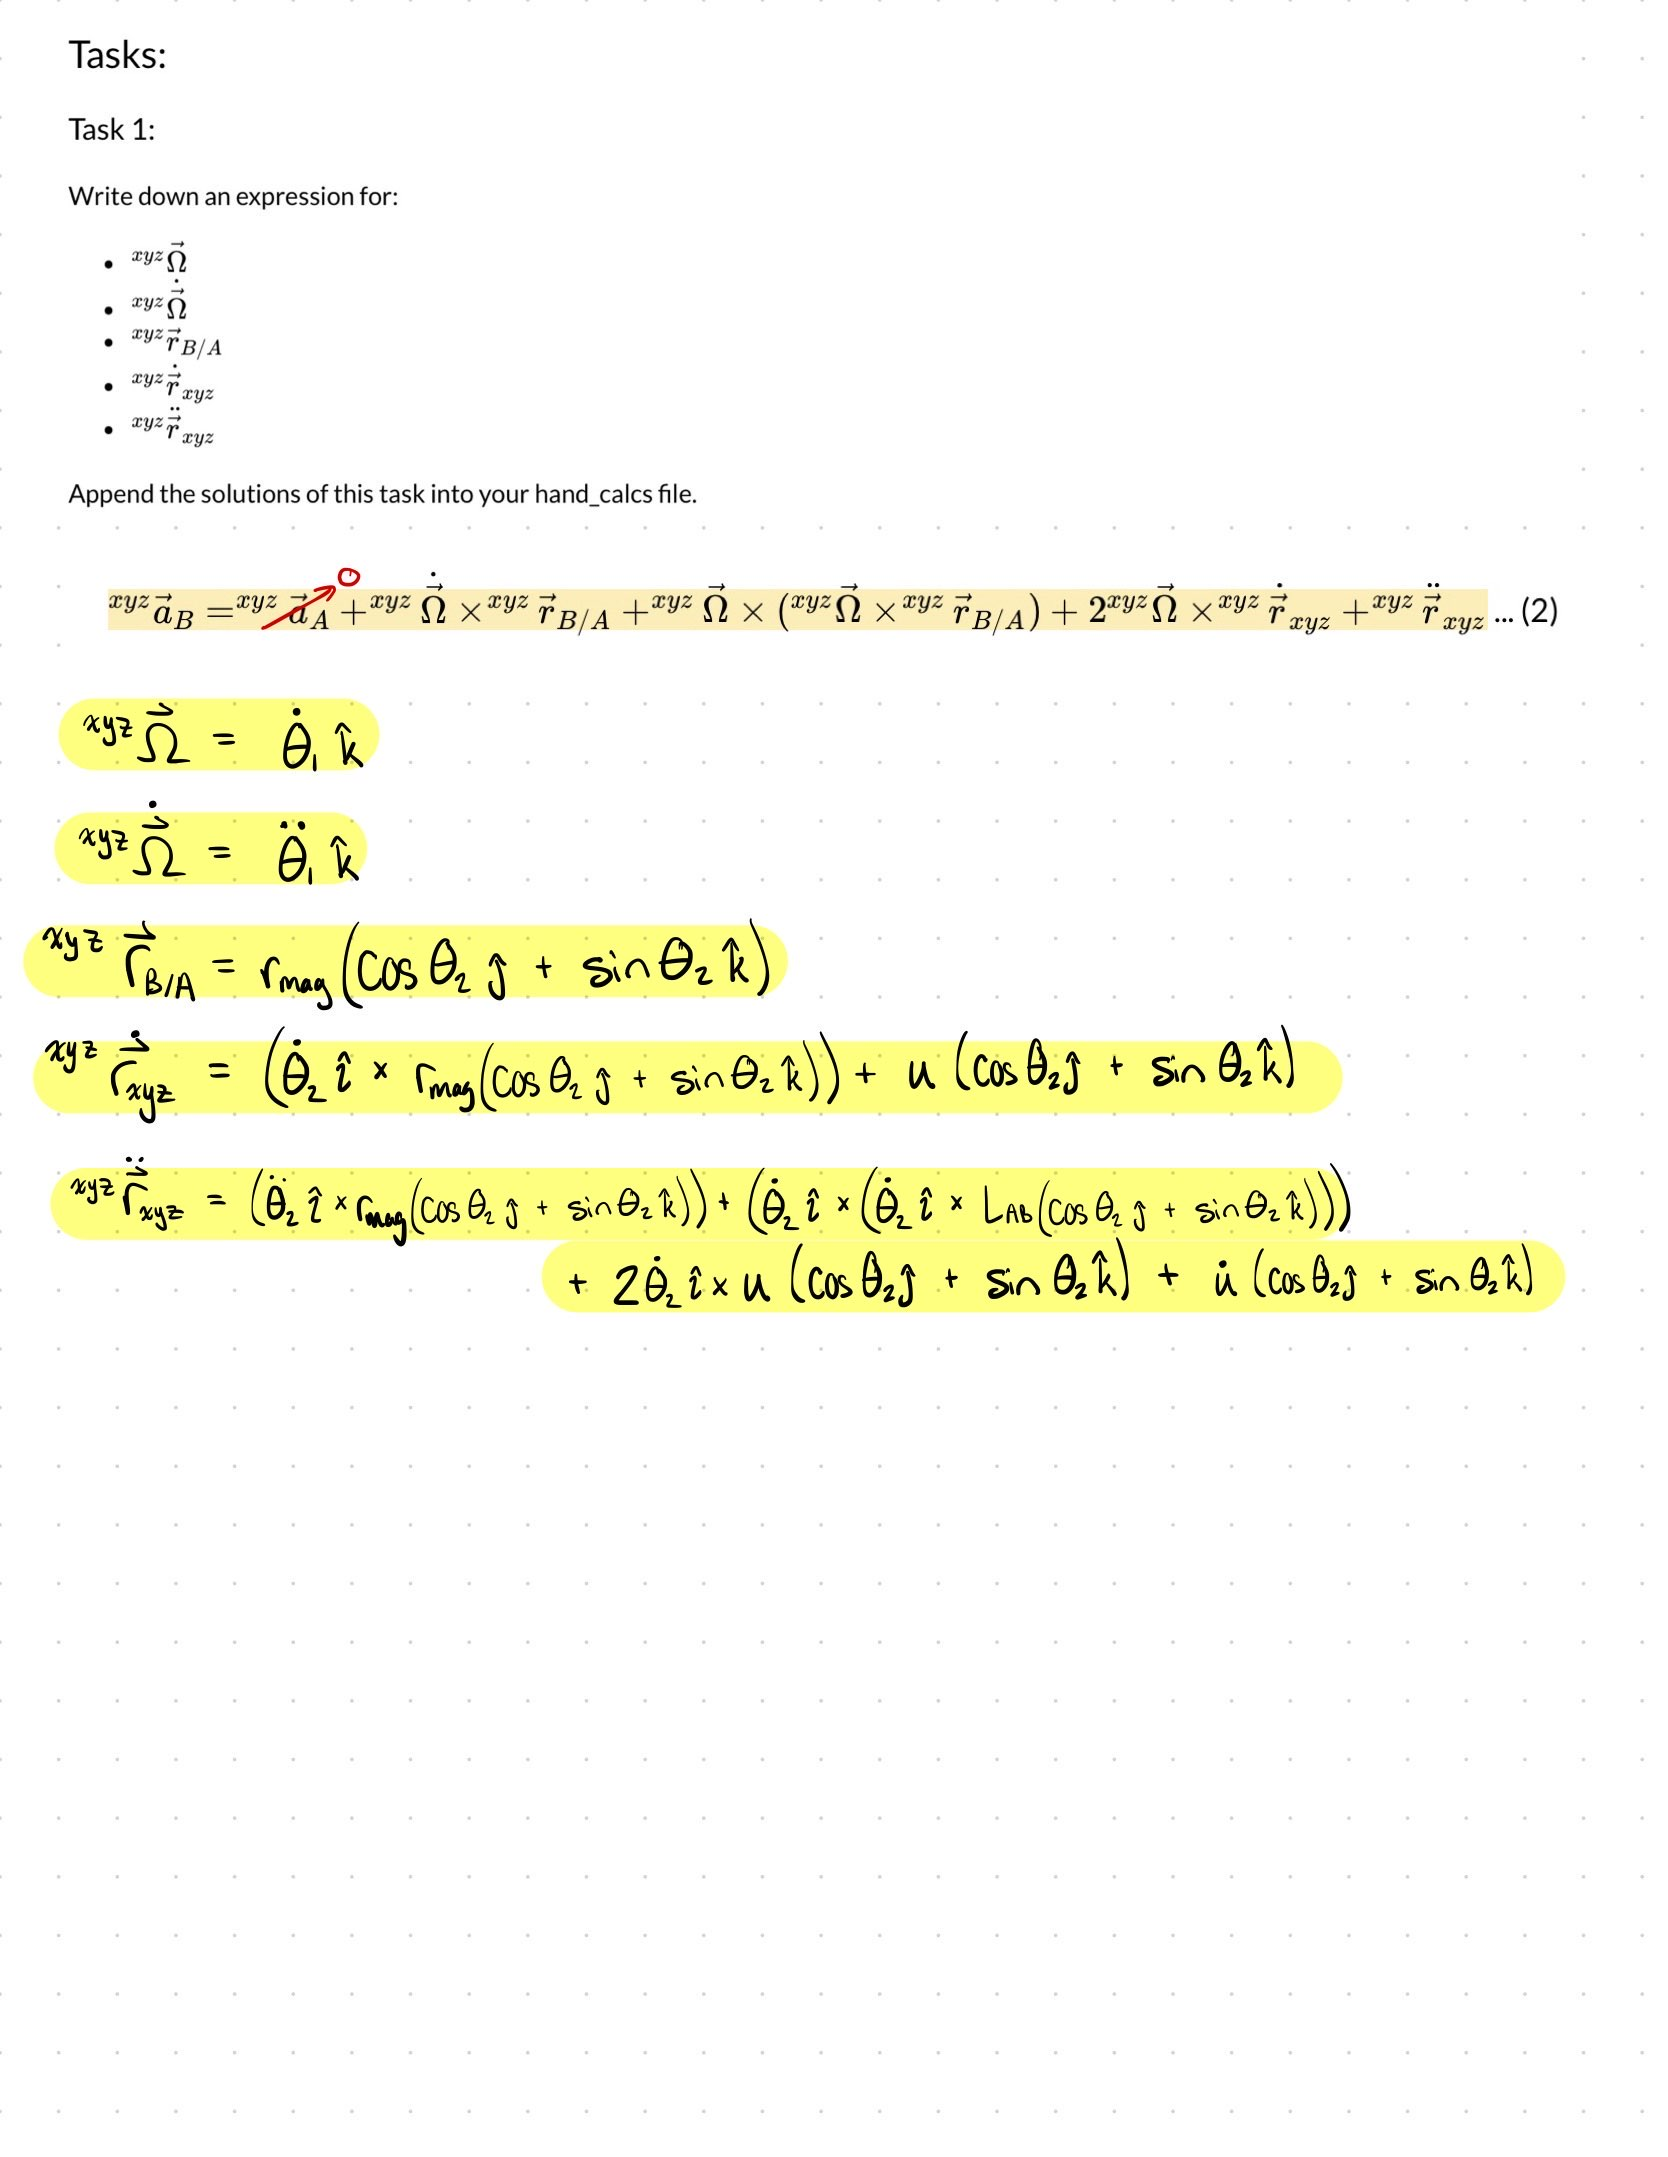

## Task 2: 

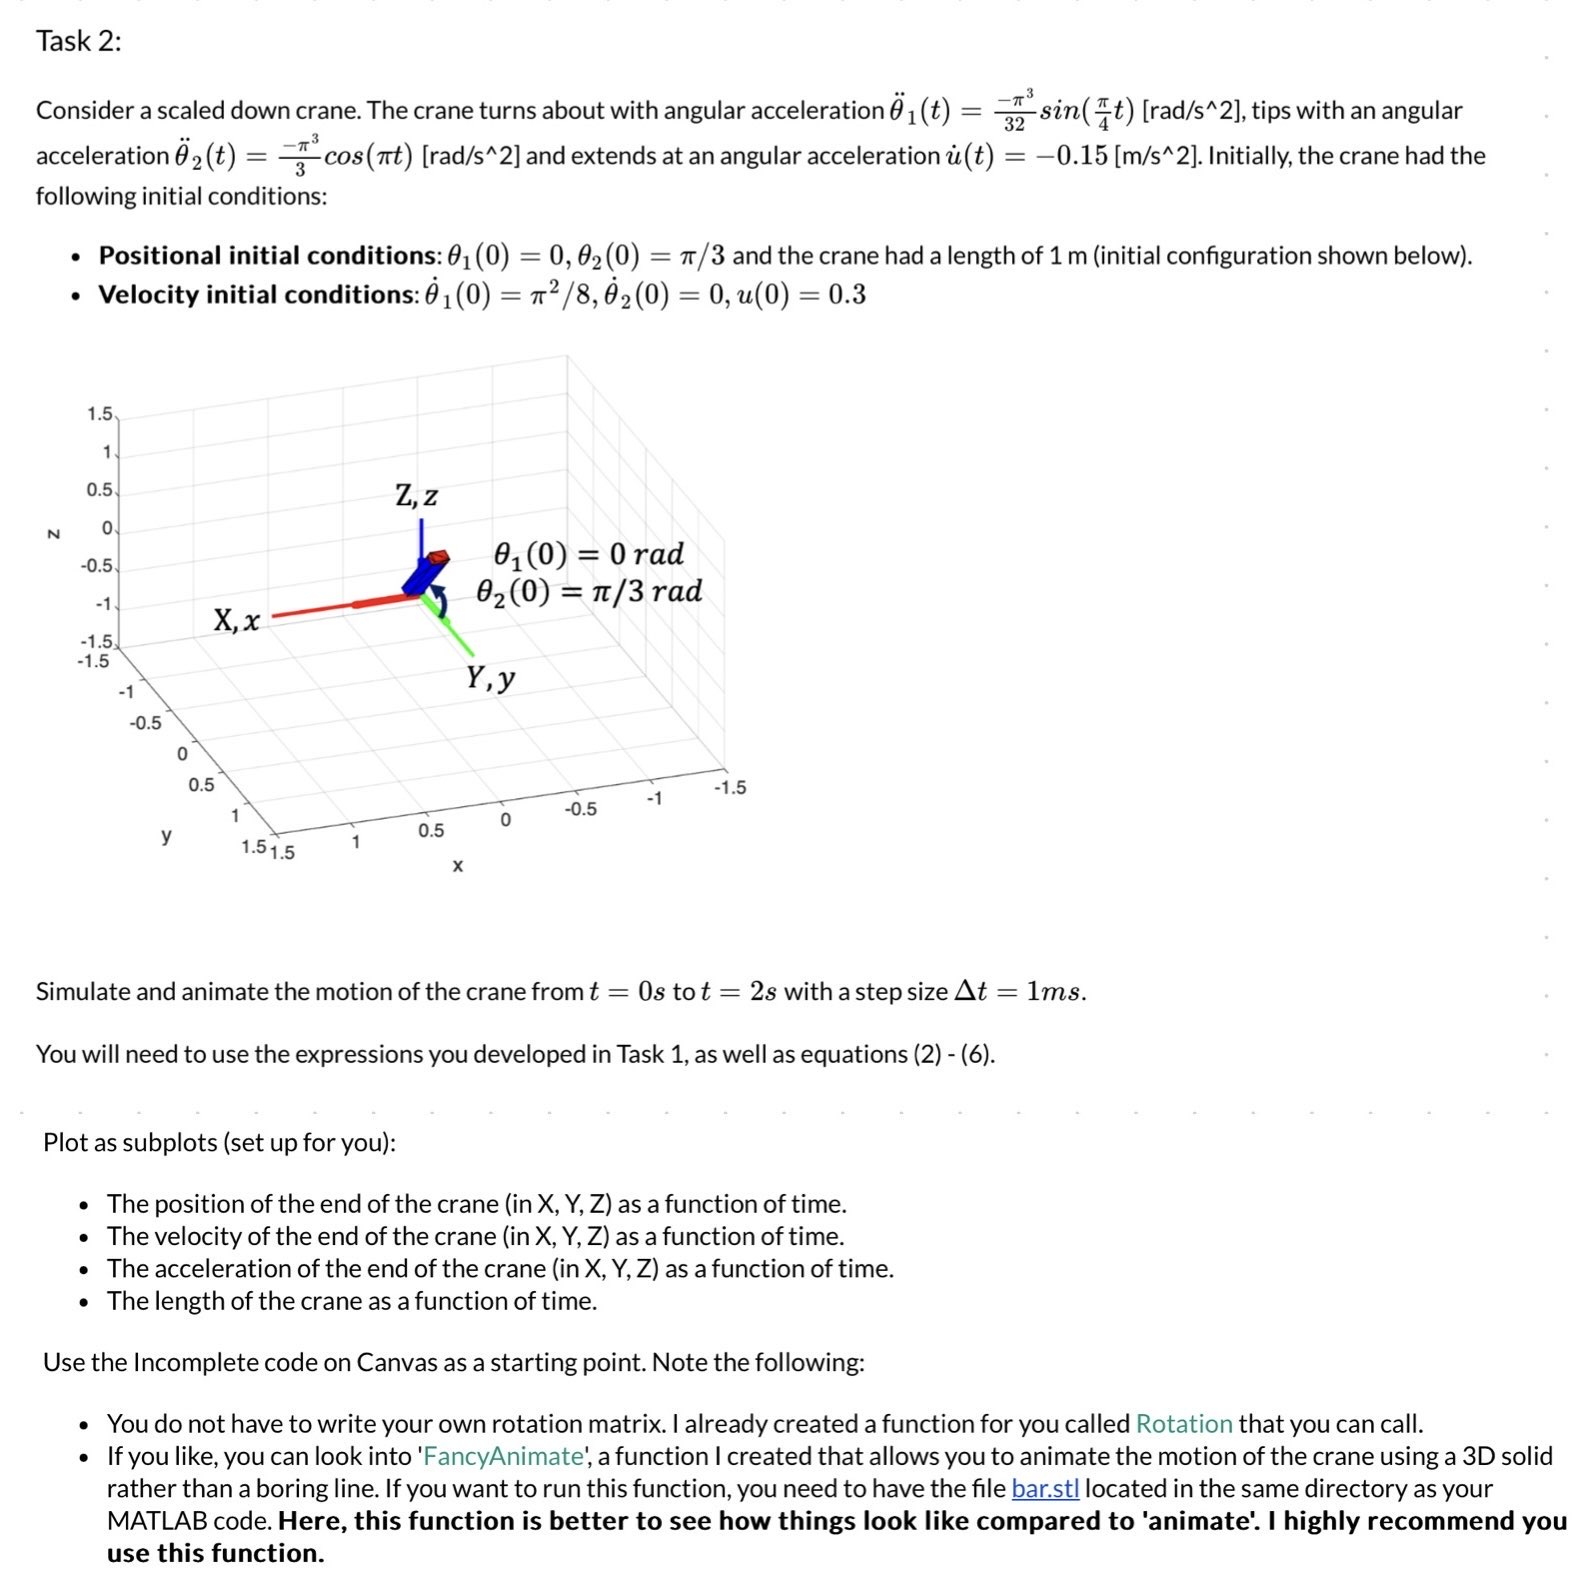

The goal of this code is to simulate and animate the motion of a scaled-down crane. The crane can undergo 2 rotations (that intersect at A) and the length of the crane changes as well.% sample code (3D velocity kinematics)

clear
clc

dt = 0.001; % [s] step size
t = 0:dt:2; % [s] simulate for a duration of 2 second total. This should
% be your time array. 
PlaybackSpeedMultiplier = 10; % do not change.

% velocity initial conditions
w1(1) = (pi^2)/8; % [rad/s] angular velocity magnitude about the Z axis
% initially (primary) 
w2(1) = 0; % [rad/s] angular velocity magnitude about the x axis
% initially (secondary) 
u(1) = 0.3; % [m/s] magnitude of velocity of crane extension outwards
% initially. 

% positional initial conditions
theta1(1) = 0; % [rad] initial angle, theta1(0).
theta2(1) = pi/3; % [rad] initial angle, theta2(0).
r_mag(1) = 1; % [m] length of the crane initially

% Simulation loop:
for i=1:length(t)
    w1_dot(i) = (-(pi^3)/32)*sin((pi/4)*t(i)); % [rad/s^2] angular
    % acceleration theta1_ddot magnitude as a function of time. 
    w2_dot(i) = (-(pi^3)/3)*cos(pi*t(i)); % [rad/s^2] angular
    % acceleration theta2_ddot magnitude as a function of time. 
    u_dot(i) = -0.15; % [m/s^2] Extension acceleration as a function of time.
    
    % Defining the terms of the acceleration equation in vectors
    Omega(:,i) = [0; 0; w1(i)];
    Omega_dot(:,i) = [0; 0; w1_dot(i)];
    xyz_w2_vec(:,i) = [w2(i); 0; 0];
    xyz_w2_dot_vec(:,i) = [w2_dot(i); 0; 0];
    
    % Position of r_A/B in the xyz coordinate system
    xyz_r(:,i) = [0; r_mag(i)*cos(theta2(i)); r_mag(i)*sin(theta2(i))];
    
    % Vectors for u for calculating xyz_r_xyz_dot and xyz_r_xyz_ddot
    u_vec(:,i) = [0; u(i)*cos(theta2(i)); u(i)*sin(theta2(i))];
    u_dot_vec(:,i) = [0; u_dot(i)*cos(theta2(i)); u_dot(i)*sin(theta2(i))];
    
    xyz_r_xyz_dot(:,i) = cross(xyz_w2_vec(:,i), xyz_r(:,i)) + u_vec(:,i);
    xyz_r_xyz_ddot(:,i) = cross(xyz_w2_dot_vec(:,i), xyz_r(:,i)) + cross(xyz_w2_vec(:,i), cross(xyz_w2_vec(:,i), xyz_r(:,i))) + cross(2*xyz_w2_vec(:,i), u_vec(:,i)) + u_dot_vec(:,i);
    
    % Velocity and Acceleration of Point B from Point A in the xyz
    % coordinates 
    xyz_v(:,i) = cross(Omega(:,i), xyz_r(:,i)) + xyz_r_xyz_dot(:,i);
    xyz_a(:,i) = cross(Omega(:,i), xyz_r(:,i)) + cross(Omega(:,i), cross(Omega(:,i), xyz_r(:,i))) + cross(2*Omega(:,i), xyz_r_xyz_dot(:,i)) + xyz_r_xyz_ddot(:,i);

    % Now we go back to the XYZ frame using a rotation matrix about Z:
    XYZ_R_xyz = Rotation('z',theta1(i)); % go back to the fixed frame using a rotation matrix
    XYZ_a(:,i) = XYZ_R_xyz*xyz_a(:,i); % Absolute acceleration of B (now described using XYZ coordinates)
    
    % We find the new velocity of the arm in the XYZ frame through
    % numerical integration.
    XYZ_v(:,i) = XYZ_R_xyz*xyz_v(:,i);
    % We also find the new position of the arm in the XYZ frame through
    % numerical integration.
    XYZ_r(:,i) = XYZ_R_xyz*xyz_r(:,i);

    % Find the next angular velocities:
    w1(i+1) = w1(i) + w1_dot(i)*dt;
    w2(i+1) = w2(i) + w2_dot(i)*dt;

    % Find the next angle
    theta1(i+1) = theta1(i) + w1(i)*dt + 0.5*w1_dot(i)*(dt^2);
    theta2(i+1) = theta2(i) + w2(i)*dt + 0.5*w2_dot(i)*(dt^2);

    % find the next extension velocity
    u(i+1) = u(i) + u_dot(i)*dt;

    r_mag(i+1) = r_mag(i) + u(i)*dt + 0.5*u_dot(i)*(dt^2); % r_mag at each time step
end

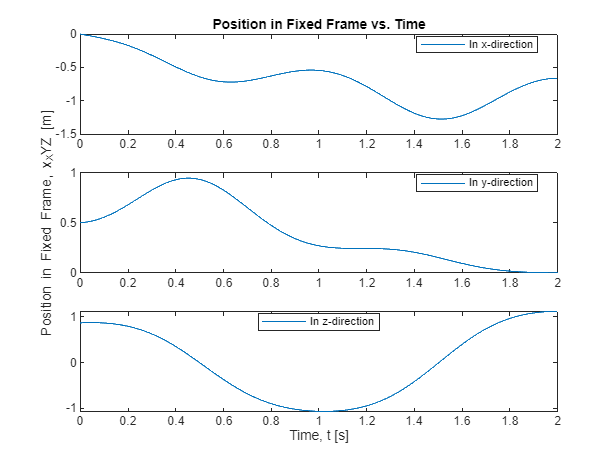

% Position of the End of the Crane in the Fixed Frame
figure(1);
hold on
grid on
subplot(3, 1, 1);
plot(t, XYZ_r(1,:));
legend("In x-direction", "Location","best");
title("Position in Fixed Frame vs. Time");
subplot(3, 1, 2);
plot(t, XYZ_r(2,:))
legend("In y-direction", "Location","best");
ylabel("Position in Fixed Frame, x_XYZ [m]");
subplot(3, 1, 3);
plot(t, XYZ_r(3,:))
legend("In z-direction", "Location","best");
xlim([0,2]);
xlabel("Time, t [s]");

Figure 1 depicts the position of the end of the crane, point B, in the global fixed coordinates XYZ throughout the course of the simulation through three subplots. Each subplot depicts a different axis with the first being in the X-direction, the second being in the Y-direction, and the last subplot being in the Z-direction. I have adjusted the graphs to all consistently display the entire course of the experiment, 2 seconds.

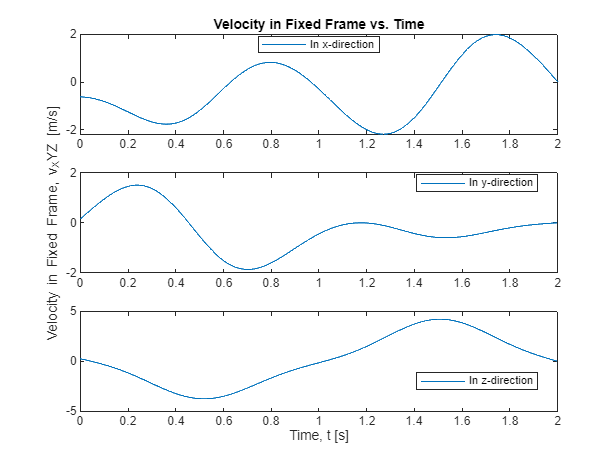

% Velocity of the End of the Crane in the Fixed Frame
figure(2);
hold on
grid on
subplot(3, 1, 1);
plot(t, XYZ_v(1,:))
legend("In x-direction", "Location","best");
title("Velocity in Fixed Frame vs. Time");
subplot(3, 1, 2);
plot(t, XYZ_v(2,:))
legend("In y-direction", "Location","best");
ylabel("Velocity in Fixed Frame, v_XYZ [m/s]");
subplot(3, 1, 3);
plot(t, XYZ_v(3,:))
legend("In z-direction", "Location","best");
xlim([0,2]);
xlabel("Time, t [s]");

Figure 2 depicts the velocity of the end of the crane, point B, in the global fixed coordinates XYZ throughout the course of the simulation through three subplots. Each subplot depicts a different axis with the first being in the X-direction, the second being in the Y-direction, and the last subplot being in the Z-direction. I have adjusted the graphs to all consistently display the entire course of the experiment, 2 seconds.

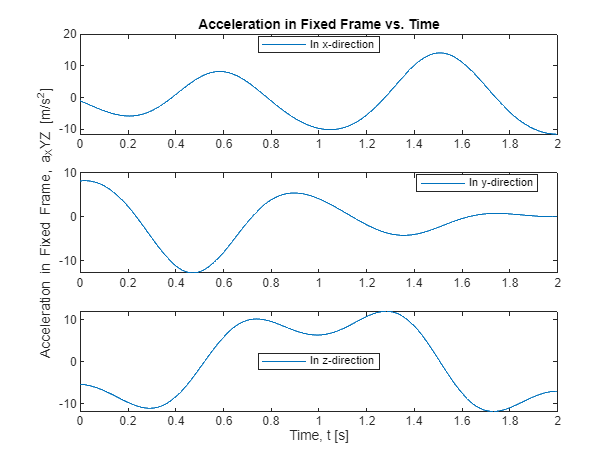

% Acceleration of the End of the Crane in the Fixed Frame
figure(3);
hold on
grid on
subplot(3, 1, 1);
plot(t, XYZ_a(1,:))
legend("In x-direction", "Location","best");
title("Acceleration in Fixed Frame vs. Time");
subplot(3, 1, 2);
plot(t, XYZ_a(2,:))
legend("In y-direction", "Location","best");
ylabel("Acceleration in Fixed Frame, a_XYZ [m/s^2]");
subplot(3, 1, 3);
plot(t, XYZ_a(3,:))
legend("In z-direction", "Location","best");
xlim([0,2]);
xlabel("Time, t [s]");

Figure 3 depicts the acceleration of the end of the crane, point B, in the global fixed coordinates XYZ throughout the course of the simulation through three subplots. Each subplot depicts a different axis with the first being in the X-direction, the second being in the Y-direction, and the last subplot being in the Z-direction. I have adjusted the graphs to all consistently display the entire course of the experiment, 2 seconds.

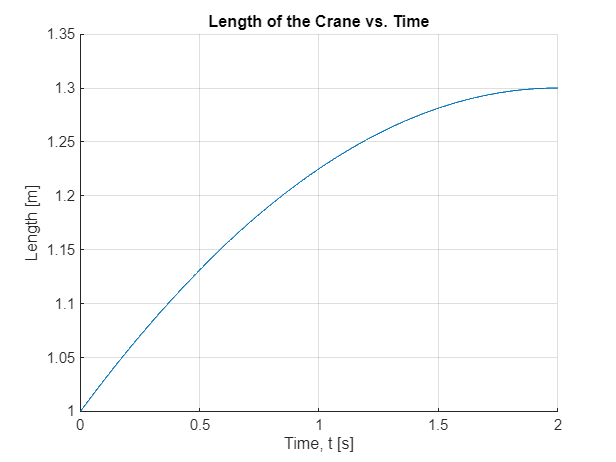

% Length of the Crane
figure(4);
hold on
grid on
plot(t, r_mag(1,1:end-1))
ylabel("Length [m]");
xlabel("Time, t [s]");
title("Length of the Crane vs. Time");

Figure 4 depicts the distance from the rotation point of the crane, point A, and the end of the crane, point B. Due to the crane's length increasing throughout the course of the 2 seconds shown in the simulation the slope of the line shown in this plot is always positive. The length the crane ends at 1.3 m at the end of the 2 seconds. 

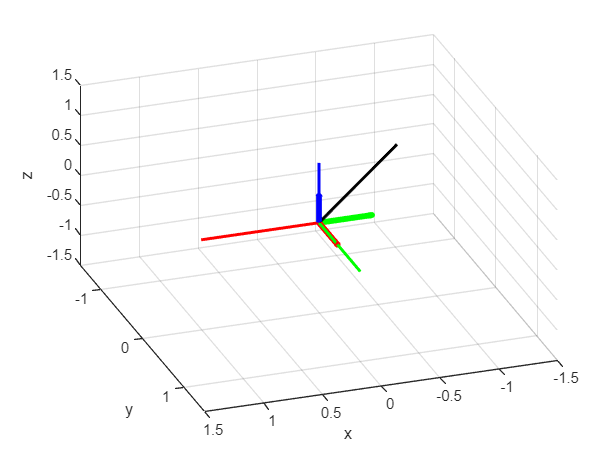

% Animate the motion (using lines)
animate(XYZ_r, theta1, PlaybackSpeedMultiplier);

Figure 5 depicts the animated crane as it rotates about the Z axis whilst extending the beam and rotating the beam up in the j axis.

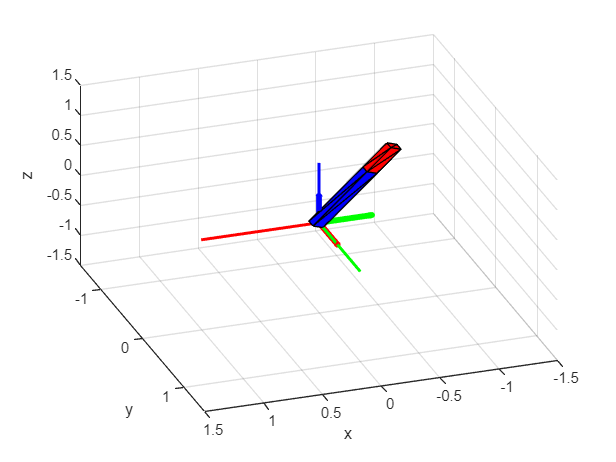

% Fancier animation using some STL files to represent the structure
% rather than lines
FancyAnimate(XYZ_r, theta1,theta2, PlaybackSpeedMultiplier);

Figure 6 depicts the Fancy Animate version of the previously described Figure 1.

## Functions

Below are some functions I used for convenience:

**Rotation**: Produces a rotation matrix about a chosen axis and a chosen angle.

Inputs:

- axis: a string that specifies the axis of rotation (string).

- theta: the angle of rotation about the specified axis (in rad).

**Animate**: An animation loop that produces the line plots.

Inputs: 

- Trajectory :a 3xn matrix representing the XYZ coordinates of the end of the arm.

- theta1: a 1xn matrix representing the angle theta1 as a function of time. (used to find the orientation of the rotating frame at each instance in time).

- PlaybackSpeedMultiplier: an integer (>=1) value that allows you to speed up the animation by that amount. PlaybackSpeedMultiplier = 2 makes your animation twice as fast on your display. 

**FancyAnimate**: Produces a fancier animation using a 3D solid rather than lines.

Note that FancyAnimate requires 'bar.stl' to be in the same directory as this matlab file.

Inputs:

- Trajectory :a 3xn matrix representing the XYZ coordinates of the end of the arm.

- theta1: a 1xn vector representing the angle theta1 as a function of time. (used to find the orientation of the rotating frame at each instance in time).

- theta2: a 1xn vector representing the angle theta2 as a function of time.

- PlaybackSpeedMultiplier: an integer (>=1) value that allows you to speed up the animation by that amount. PlaybackSpeedMultiplier = 2 makes your animation twice as fast on your display. 

function R = Rotation(axis, theta)
    if axis == 'x' % your rotation is about the x axis
        R = [1 0 0
             0 cos(theta) -sin(theta)
             0 sin(theta) cos(theta)];
    elseif axis == 'y' % your rotation is about the y axis
        R = [cos(theta) 0 sin(theta)
             0 1 0
             -sin(theta) 0 cos(theta)];
    else % your rotation is about the z axis
        R = [cos(theta) -sin(theta) 0
             sin(theta) cos(theta) 0
             0 0 1];
    end
end

function animate(Trajectory, theta1,PlaybackSpeedMultiplier)
    % here, trajectory is a 3xn vector
    % each row is the [X,Y,Z] position of the end of the crane
    for i=1:PlaybackSpeedMultiplier:length(Trajectory(1,:))
        figure(5)
        plot3([0;1],[0;0],[0;0],'r',LineWidth=2)
        hold on
        plot3([0;0],[0;1],[0;0],'g',LineWidth=2)
        plot3([0;0],[0;0],[0;1],'b',LineWidth=2)
        XYZ_R_xyz = Rotation('z',theta1(i));

        x = Rotation("z", theta1(i)) * [0.5; 0; 0];
        y = Rotation("z", theta1(i)) * [0; 0.5; 0];
        z = [0; 0; 0.5];

        quiver3(0, 0, 0,  x(1), x(2), x(3), 'Color', 'red', 'LineWidth', 4);
        quiver3(0, 0, 0,  y(1), y(2), y(3), 'Color', 'green', 'LineWidth', 4);
        quiver3(0, 0, 0,  z(1), z(2), z(3), 'Color', 'blue', 'LineWidth', 4);
        plot3([0;Trajectory(1,i)],[0;Trajectory(2,i)],[0,Trajectory(3,i)],'k',LineWidth=2)
        hold off
        xlabel 'x'
        ylabel 'y'
        zlabel 'z'
        % view([150,30]);
        view([160.69 40.76]);
        grid
        xlim ([-1.5,1.5])
        ylim ([-1.5,1.5])
        zlim ([-1.5,1.5])
        pause(0.01)
    end
end

function FancyAnimate(Trajectory, theta1,theta2,PlaybackSpeedMultiplier)
    % here, trajectory is a 3xn vector
    % each row is the [X,Y,Z] position of the end of the crane

    Bar = stlread('Bar.stl');
    BarPoints1 = [0.001,0.001,0.001].*Bar.Points;
    BarPoints1Starting = (Rotation('z',pi/2)*BarPoints1')';
    BarConnectivity1 = Bar.ConnectivityList;
    BarPoints2 = [0.001/9,0.001,0.001].*Bar.Points+[0.9,0,0];
    BarPoints2Starting = (Rotation('z',pi/2)*BarPoints2')';
    BarConnectivity2 = Bar.ConnectivityList;

    for i=1:PlaybackSpeedMultiplier:length(Trajectory(1,:))
        figure(6)
        plot3([0;1],[0;0],[0;0],'r',LineWidth=2)
        hold on
        plot3([0;0],[0;1],[0;0],'g',LineWidth=2)
        plot3([0;0],[0;0],[0;1],'b',LineWidth=2)
        XYZ_R_xyz = Rotation('z',theta1(i));

        x = Rotation("z", theta1(i)) * [0.5; 0; 0];
        y = Rotation("z", theta1(i)) * [0; 0.5; 0];
        z = [0; 0; 0.5];

        quiver3(0, 0, 0,  x(1), x(2), x(3), 'Color', 'red', 'LineWidth', 4);
        quiver3(0, 0, 0,  y(1), y(2), y(3), 'Color', 'green', 'LineWidth', 4);
        quiver3(0, 0, 0,  z(1), z(2), z(3), 'Color', 'blue', 'LineWidth', 4);
        
        R = Rotation('z',theta1(i))*Rotation('x',theta2(i));
        BarPoints1 = (R*BarPoints1Starting')';
        BarPoints2 = [0.001/9*(norm(Trajectory(:,i))-0.9)/0.1,0.001,0.001].*Bar.Points+[0.9,0,0];
        BarPoints2Starting = (Rotation('z',pi/2)*BarPoints2')';
        BarPoints2 = (R*BarPoints2Starting')';
        trimesh(BarConnectivity1,BarPoints1(:,1),BarPoints1(:,2),BarPoints1(:,3),'edgecolor','k','facecolor','b')
        trimesh(BarConnectivity2,BarPoints2(:,1),BarPoints2(:,2),BarPoints2(:,3),'edgecolor','k','facecolor','r')

        hold off
        xlabel 'x'
        ylabel 'y'
        zlabel 'z'
        % view([150,30]);
        view([160.69 40.76]);
        grid
        xlim ([-1.5,1.5])
        ylim ([-1.5,1.5])
        zlim ([-1.5,1.5])
        pause(0.1)
    end
end